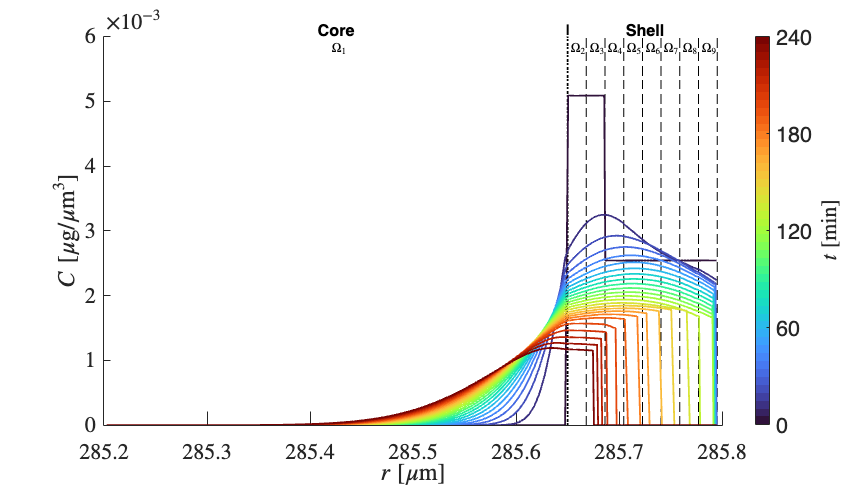

load("test_real/exp_2412_U.mat", "U_all", "gridsB", "dt_mass", "T", 'exp_dX');
core_layers = 3;
subid = 2;
Nl = size(U_all, 1);
Nt = size(U_all, 2);
Ts = 0:dt_mass:T;
Nxs = zeros(Nl, 1); 
for i = 1 : Nl
    Nxs(i) = length(U_all{i});
end
Lxs = [0; cumsum(Nxs)];
Nx = Lxs(end);

R0 = 285.65;
exp_thick = sum(exp_dX, 2)';
thmax = exp_thick(1) - R0;
Lbound = R0 + thmax / (Nl-core_layers) .* (0:Nl-core_layers);

X = zeros(Nx, 1);
U = zeros(Nx, Nt);
for i = 1 : Nl
    X(Lxs(i)+1:Lxs(i+1)) = gridsB{i};
    for t = 1 : Nt
        U(Lxs(i)+1:Lxs(i+1), t) = U_all{i, t}(:, subid);
    end
end

fs = 24;
xmin = 285.2;
plot_idxs = X > xmin;
fig = figure();
ax = axes( ...
    'Parent', fig, ...
    'TickLabelInterpreter', 'latex', ...
    'FontSize', fs ...
);

cmap = turbo(Nt); % or parula, turbo, etc.

hold(ax, 'on');
plk = plot(ax, ...
    [R0, R0], [0, 0.0060], ...
    'k:', ...
    'LineWidth', 2 ...
);
for l = 1 : Nl-core_layers
    plc = plot(ax, ...
        [Lbound(l+1) Lbound(l+1)], [0, 0.0060], ...
        'k--' ...
    );
    text((Lbound(l)+Lbound(l+1))/2+0.001, 0.0058, "$\Omega_" + (l+1) + "$", ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'middle', ...
        'BackgroundColor', 'none', ...
        'Margin', 1, ...
        'FontSize', 15, ...
        'FontWeight', 'bold', ...
        'Color', 'k', ...
        ... 'Rotation', 90, ...
        'Interpreter', 'latex' ...
    );
end
text((R0+xmin)/2+0.003, 0.0058, "$\Omega_1$", ...
    'HorizontalAlignment', 'center', ...
    'VerticalAlignment', 'middle', ...
    'BackgroundColor', 'none', ...
    'Margin', 1, ...
    'FontSize', 15, ...
    'FontWeight', 'bold', ...
    'Color', 'k', ...
    ... 'Rotation', 90, ...
    'Interpreter', 'latex' ...
);
text((R0+xmin)/2, 0.0061, "Core", ...
    'HorizontalAlignment', 'center', ...
    'VerticalAlignment', 'middle', ...
    'BackgroundColor', 'none', ...
    'Margin', 1, ...
    'FontWeight', 'bold', ...
    'Color', 'k', ...
    'FontSize', 18 ...
);
text(R0, 0.0061, "|", ...
    'HorizontalAlignment', 'center', ...
    'VerticalAlignment', 'middle', ...
    'BackgroundColor', 'none', ...
    'Margin', 1, ...
    'FontWeight', 'bold', ...
    'Color', 'k', ...
    'FontSize', 16 ...
);
text(R0+.075, 0.0061, "Shell", ...
    'HorizontalAlignment', 'center', ...
    'VerticalAlignment', 'middle', ...
    'BackgroundColor', 'none', ...
    'Margin', 1, ...
    'FontWeight', 'bold', ...
    'Color', 'k', ...
    'FontSize', 18 ...
);
for t = 1 : 2 : Nt
    plot(ax, ...
        X(plot_idxs), U(plot_idxs, t), ...
        'Color', cmap(t, :), ...
        'LineWidth', 2 ...
    )
end
hold(ax, 'off');

% legend([plk, plc], 'Core Boundary', 'Coating Layers', "Location", 'northwest', 'Interpreter', 'latex')
xlabel('$r$ [$\mu$m]', 'Interpreter', 'latex', 'FontSize', fs);
ylabel('$C$ [$\mu$g/$\mu$m$^3$]', 'Interpreter', 'latex', 'FontSize', fs);
ax.FontSize = fs;
xlim([xmin, 285.8])
% title('u(x, t): coloured by timestamp');
colormap(cmap);
cb = colorbar;
cb.Ticks = linspace(0,1,5);
cb.TickLabels = round(linspace(Ts(1)/60, Ts(end)/60, 5));
cb.Label.String = '$t$ [min]';
cb.Label.Interpreter = 'latex';
cb.FontSize = fs;

fig.Position = [0 0 16*60 9*60];

exportgraphics(fig, "img/experiment-profile.png", 'Resolution', 300);
exportgraphics(fig, "img/experiment-profile.pdf");

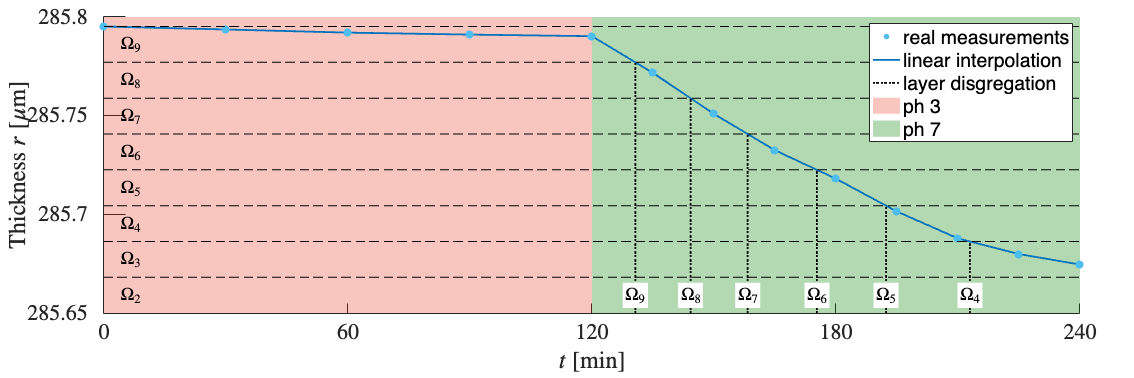

clear
fs = 24;
R0 = 285.65;
load("test_real/exp_2412_SD.mat", "M_released", "dt_mass", "T");
M_released_bad = M_released;
Ts_bad = 0:dt_mass:T;
load("test_real/exp_2412_U.mat", "M_released", "dt_mass", "T", "exp_t", "exp_mrel", "exp_dX");
Nl = 8;
Ts = 0:dt_mass:T;
exp_thick = sum(exp_dX, 2)';
thmax = exp_thick(1) - R0;

Lbound = R0 + thmax / Nl .* (0:Nl);

l2t = @(xq) interp1(exp_thick, exp_t, xq, 'linear');
Lt = l2t(Lbound);
% Lt(end) = NaN;
Lt(2) = 240*60; % used for plotting the label
% Lt(end) = 120*60; % used for plotting the label

fig = figure();
tl = tiledlayout(fig, 1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');

%% SB1
ax = nexttile(tl);
ax.TickLabelInterpreter = 'latex';
ax.FontSize = fs;
% ax = subplot(1, 2, 1, ...
%     "Parent", fig, ...
%     'TickLabelInterpreter', 'latex', ...
%     'FontSize', fs ...
% );
hold(ax, 'on');

bg1 = fill(ax, [0, 0, 120, 120], [R0, R0+.15, R0+.15, R0], [.9, 0.1, 0], 'FaceAlpha', 0.25, 'EdgeColor', 'none');
bg2 = fill(ax, [120, 120, 240, 240], [R0, R0+.15, R0+.15, R0], [0, 0.5, 0], 'FaceAlpha', 0.3, 'EdgeColor', 'none');

pl = plot(ax, ...
    exp_t/60, exp_thick, ...
    '-', ...
    'Color', "#0072BD", ...
    'LineWidth', 2 ...
);
sc = scatter(ax, ...
    exp_t/60, exp_thick, ...
    80, [0.3010 0.7450 0.9330], 'o', 'filled', ...
    'LineWidth', 2 ...
);
t0 = exp_t(1)/60;
t1 = exp_t(end)/60;
for i = 1 : Nl
    plot(ax, [t0 t1], [Lbound(i+1) Lbound(i+1)], '--k');
    % if idx > 4
    %     tlab = t1*.99;
    %     labalign = 'right';
    % else
    %     tlab = t1*.01;
    %     labalign = 'left';
    % end
    xtmp = (Lbound(i) + Lbound(i+1)) / 2;
    text(t1*.015, xtmp, "$\Omega_" + (i+1) + "$", ...
        'HorizontalAlignment', 'left', ...
        'VerticalAlignment', 'middle', ...
        'BackgroundColor', 'none', ...
        'Margin', 1, ...
        'FontWeight', 'bold', ...
        "Interpreter", 'latex', ...
        'FontSize', 20, ...
        'Color', 'k' ...
    );
end
% scatter(ax, Lt/60, Lbound);
for i = 3:Nl
    dl = plot(ax, ...
        [Lt(i) Lt(i)]/60, [R0 Lbound(i)], ...
        'k:', ...
        'LineWidth', 2 ...
    );
    text((Lt(i))/60, R0+.009, "$\Omega_" + (i+1) + "$", ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'middle', ...
        'BackgroundColor', 'white', ... [0, 0.5, 0, 0.3], ...
        'Margin', 1, ...
        'FontWeight', 'bold', ...
        'Color', 'k', ...
        'FontSize', 20, ...
        'Interpreter', 'latex' ...
        ... 'Rotation', 90 ...
    );
end

hold(ax, 'off');

ax.XTick = 0:60:240;
xlim([0, 240]);
xlabel('$t$ [min]', 'Interpreter', 'latex')

ylabel('Thickness $r$ [$\mu$m]', 'Interpreter', 'latex')

% legend(ax, ...
%     [pl, sc], ["linear interp.", "real measur."], ...
%     'Location', 'northeast' ... 'south' ...
% );
legend(ax, ...
    [sc, pl, dl, bg1, bg2], ["real measurements", "linear interpolation", "layer disgregation" "ph 3", "ph 7"], ...
    'Location', 'northeast' ... 'south' ...
);

% ax = axes('Position', [0 0 1 1], 'Visible', 'off');
% lgd = legend(ax, ...
%     [bg1, bg2], ["Ph 3", "Ph 7"], ...
%     'Location', 'southoutside', ...
%     'Interpreter', 'latex', ...
%     'FontSize', fs, ...
%     NumColumns=2 ...
% );
%lgd.Layout.Tile = 'south';

fig.Position = [0 0 21*60 7*60];

exportgraphics(fig, "img/experiment-disgregation.png", 'Resolution', 300);
exportgraphics(fig, "img/experiment-disgregation.pdf");

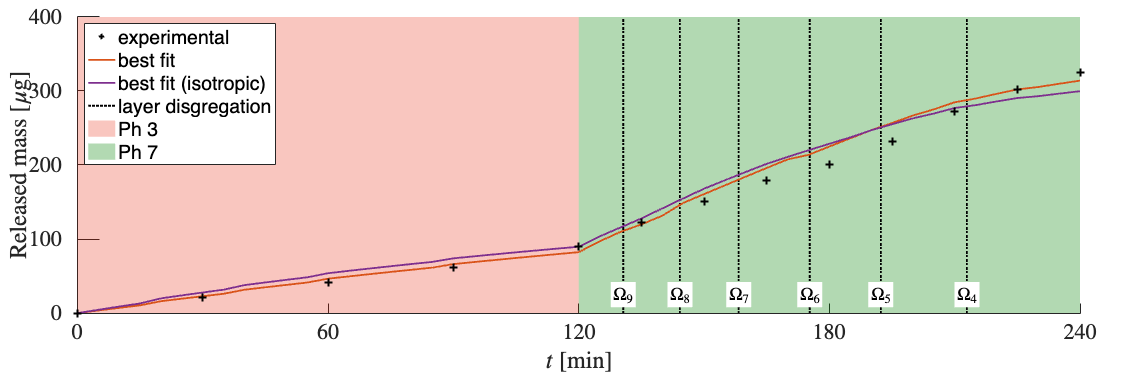

fig = figure();
tl = tiledlayout(fig, 1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');

R0 = 285.65;
%% SB2
ax = nexttile(tl);
ax.TickLabelInterpreter = 'latex';
ax.FontSize = fs;
% ax = subplot(1, 2, 2, ...
%     "Parent", fig, ...
%     'TickLabelInterpreter', 'latex', ...
%     'FontSize', fs ...
% );

hold(ax, 'on');

bg1 = fill(ax, ...
    [0, 0, 120, 120], [0, 400, 400, 0], ...
    [.9, 0.1, 0], ...
    'FaceAlpha', 0.25, ...
    'EdgeColor', 'none', ...
    'DisplayName', 'Ph 3' ...
);
bg2 = fill(ax, ...
    [120, 120, 240, 240], [0, 400, 400, 0], ...
    [0, 0.5, 0], ...
    'FaceAlpha', 0.3, ...
    'EdgeColor', 'none', ...
    'DisplayName', 'Ph 7' ...
);

for i = 3:Nl
    ld = plot(ax, ...
        [Lt(i) Lt(i)]/60, [0 400], ...
        'k:', ...
        'LineWidth', 2 ...
    );
end
for i = 3:Nl
    text((Lt(i))/60, 25, "$\Omega_" + (i+1) + "$", ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'middle', ...
        'BackgroundColor', 'white', ... [0, 0.5, 0], ...
        'Margin', 1, ...
        'FontWeight', 'bold', ...
        'Color', 'k', ...
        'FontSize', 20, ...
        'Interpreter', 'latex' ...
        ... 'Rotation', 90 ...
    );
end
% text(120, 7, "CL " + Nl, ...
%     'HorizontalAlignment', 'center', ...
%     'VerticalAlignment', 'bottom', ...
%     'BackgroundColor', 'none', ...
%     'Margin', 1, ...
%     'FontWeight', 'bold', ...
%     'Color', 'k' ...
% );
pl = plot(ax, ...
    Ts/60, cumsum(M_released(:, 2)), ...
    'Color', "#D95319", ...
    'LineWidth', 2 ...
);
pl_bad = plot(ax, ...
    Ts_bad/60, cumsum(M_released_bad(:, 2)), ...
    'LineWidth', 2, ...
    'Color', "#7E2F8E" ...
);
sc_real = scatter(ax, ...
    exp_t/60, exp_mrel, ...
    80, 'k+', ...
    'LineWidth', 2 ...
);
hold(ax, 'off');

ax.XTick = 0:60:240;
xlim([0, 240]);
xlabel('$t$ [min]', 'Interpreter', 'latex')

ylabel('Released mass [$\mu$g]', 'Interpreter', 'latex')

% legend(ax, ...
%     [pl, pl_bad, sc_real], ["best fit", "best fit (isotropic)", "reference"], ...
%     'Location', 'northwest' ...
% );
legend(ax, ...
    [sc_real, pl, pl_bad, ld, bg1, bg2], ["experimental", "best fit", "best fit (isotropic)", "layer disgregation", "Ph 3", "Ph 7"], ...
    'Location', 'northwest' ...
);

% ax = axes('Position', [0 0 1 1], 'Visible', 'off');
% lgd = legend(ax, ...
%     [bg1, bg2], ["Ph 3", "Ph 7"], ...
%     'Location', 'southoutside', ...
%     'Interpreter', 'latex', ...
%     'FontSize', fs, ...
%     NumColumns=2 ...
% );
%lgd.Layout.Tile = 'south';

fig.Position = [0 0 21*60 7*60];

exportgraphics(fig, "img/experiment-release.png", 'Resolution', 300);
exportgraphics(fig, "img/experiment-release.pdf");